# Math 121 Exam 3 Function Directory

This file contains a list of the functions you've written and how to use them.

## Numerical Integration

MGL >= Romberg >> composite simpson

### Basic Methods

#### 1. Midpoint

format long;
a=2; b=2.5;
f = @(x) (log(x))^3/(3*x);
mid = (b-a)*f((a+b)/2)

mid =    0.039501781338362


trueVal = 1/12*((log(2.5))^4 - (log(2))^4)

trueVal =    0.039506174626272


relMid = (mid-trueVal)/trueVal

relMid =     -1.112050952049844e-04


fprintf('%.6f',relMid);

-0.000111

#### 2. Trapezoid

a=2; b=2.5;
f = @(x) (log(x))^3/(3*x);
trap = (b-a)/2*(f(a)+f(b))

trap =    0.039519605475190


relTrap = (trap-trueVal)/trueVal

relTrap =      3.399683478509422e-04


fprintf('%.6f',relTrap);

0.000340

#### 3. Simpson's

a=2; b=2.5;
f = @(x) (log(x))^3/(3*x);
simp = (b-a)/6*(f(a)+4*f((a+b)/2)+f(b))

simp =    0.039507722717305


relSimp = (simp-trueVal)/trueVal

relSimp =      3.918605248026590e-05


fprintf('%.6f',relSimp);

0.000039

### Composite Methods

Split into smaller intervals

#### 1. Composite Simpson

I = MyCompositeSimpson(f, a, b, n)

a =-1; b =1; f = @(x) sqrt( 1 + x^2 / (1 - x^2) );
n = 10000; 
I = MyCompositeSimpson(f, a, b, n)

I =    Inf


#### 2. Composite Trapezoid

I = MyCompositeTrapezoid(f,a,b,n)

a =-1; b =1; f = @(x) sqrt( 1 + x^2 / (1 - x^2) );
n = 10000; 
I = MyCompositeTrapezoid(f, a, b, n)

I =    Inf


#### 3. Romberg

M121_E3b_Romberg_Method_Numerical_Integration.mlx

or

I=MyNewRomberg(f,a,b,m) 

a =-0.97; b =0.97; f = @(x) sqrt( 1 + (-x / (1 - x^2))^2 );
m = 10; 
I=MyNewRomberg(f,a,b,m) 

I =    3.864617202450800


#### 4. Comp Midpoint

I=MyCompMidpoint(f,a,b,n)

a =-1; b =1; f = @(x) sqrt( 1 + x^2 / (1 - x^2) );
n = 10000; 
I=MyCompMidpoint(f,a,b,n)

I =    3.124485419111100


### Gaussian Quadratures

#### 1. Gaussian Quadratures

I = MyGaussianQuad(f,a,b)         %exact results for degree n <= 3

#### 2. Composite Gaussian Quadratures

I = MyCompGaussianQuad(f,a,b,n)

### Legendre Polynomials

#### 1. Gaussian Legendre

I=MyGaussLegendre(f,a,b,d,n)

## Numerical Differentiation

#### 1. Three Point Formulas (Midpoint > Endpoint)

h = 0.08;
x0=0.9;
f = @(x) cos(x);
true_deriv = -sin(0.9)

true_deriv =   -0.783326909627483



fp = 1/(2*h)*(f(x0+h)-f(x0-h));
N1h = fp

N1h =   -0.782491628258726


rel_err = abs(N1h-true_deriv)/abs(true_deriv)

rel_err =    0.001066325385342



h=0.04;
fp = 1/(2*h)*(f(x0+h)-f(x0-h));
N1h2 = fp

N1h2 =   -0.783118039161922


rel_err = abs(N1h2-true_deriv)/abs(true_deriv)

rel_err =      2.666453341441542e-04


N2h = N1h2 + (N1h2 - N1h)/(4^1-1)

N2h =   -0.783326842796320



relErr = abs(N2h-true_deriv)/abs(true_deriv)

relErr =      8.531707814157539e-08


## IVP Solvers

Solving initial value problems with ODEs.

#### Euler's Method

y is the solution, f = y' is from the ODE. f is a function of both t and y. Tend to diverge from the true solution as you get farther from the IV

y(t1) = y(t0) + f(t0, y(t0);     y(t2) = y(t1) +f(t1, y(t1)

% for y' = t + y, y(1) = 1, on interval [1,2]
f = @(t,y) t + y;
a = 1; b = 2;
alp = 1; % y(a) = alp
[t,y1]=MyEuler(f,a,b,10,alp);
plot(t,y1, 'b');
hold on;

There's also higher order Taylor method, [t,y] = MyHigherTaylor(f,fp,a,b,N,alp)

#### Runge Kutta 4

f = @(t,y) t + y;
a = 1; b = 2;
alp = 1; % y(a) = alp
[t,y2] = MyRK4(f,a,b,10,alp);
plot(t,y2,'r');

legend(["Euler", "RK4"])
title("IVP solutions")

## Midpoint IVP Final Exam Q

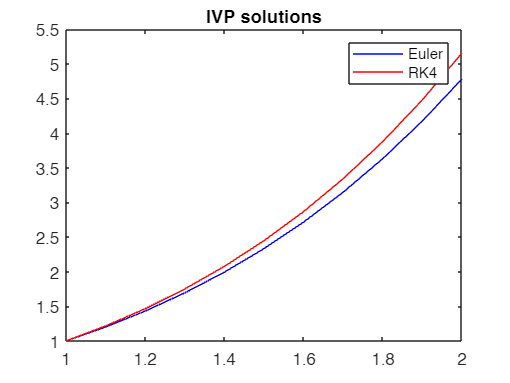

n=4;
w0 =0.5;
t0=0; t1=0.5; t2= 1; t3=1.5; t4=2;
h=(t4-t0)/n;
f=@(t,y) y-t^2+1;
[t,y] = MyRK4(f,t0,t4,20,w0);
hold off;

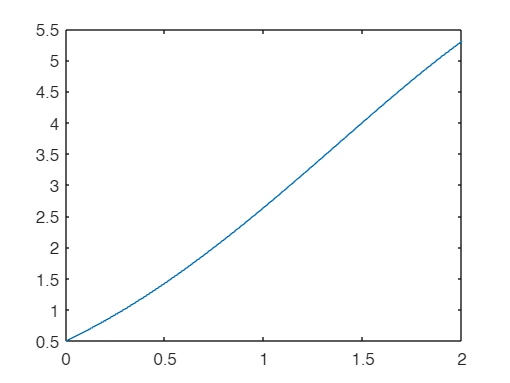

plot(t,y);

pn=myFwdNewtDivDiff(t0 +1*h,t,y)

pn = function_handle with value:
    @(x)pn(x)+coeff(i)*x.^(n-i)


pn(t0 +1*h)

ans =    1.425638395648218


pn(t2)

ans =    2.640856724185053


pn(t3)

ans =    4.009151145300419


pn(t4)

ans =    5.305464960227350



w1= w0 + h*f(t0 + h/2, w0 + h/2*f(t0,w0))

w1 =    1.406250000000000


w2 = w1 + h*f(t1 + h/2, w1 + h/2*f(t1,w1))

w2 =    2.597656250000000


w3 = w2 + h*f(t2 + h/2, w2 + h/2*f(t2,w2))

w3 =    3.939941406250000


w4 = w3 + h*f(t3 + h/2, w3 + h/2*f(t3,w3))

w4 =    5.214904785156250


## Final Q 1

f = @(x)x^3;
int(x^3,-1,1)

$$ans = \frac{2}{5}$$

Q = 1/3*f(-1)+4/3*f(0)+1/3*f(1)

Q =    0.666666666666667
